## Exercises: Task 2

Fromsa Teshome Negasa

Photonics for Security, Reliability, and Safety (PSRS)

Display Technologies (LF00CQ35-3002 J)

Piotr Bartczak, Instructor

8th May 2024

## I & II. Key Terms in Display Technology and Color Science

These are essential terms in color science and imaging, such as spectral power distribution and color models. Understanding these concepts is crucial for effectively representing, perceiving, and manipulating color across different technologies and media.

- **Spectral power distribution (SPD):** A graph showing the amount of light emitted or reflected by an object at each wavelength in the visible spectrum (typically 380nm to 760nm). It's like a fingerprint, but for light.

- **Spectral reflectance:** The ratio of light reflected by a surface at a specific wavelength compared to the light hitting it. It tells us how "colorful" an object is at different wavelengths.

- **Color models:** Mathematical representations of how colors can be created. They are like a recipe book, but for mixing colored lights or pigments. Common models include RGB and CMYK.

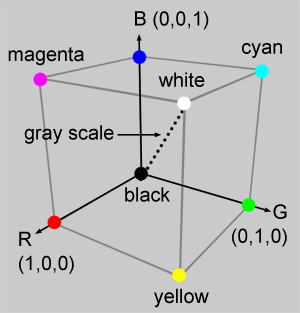

- **Color spaces:** Systems for classifying and organizing colors based on a specific color model. They act as a map of all the colors that can be created within a particular model. 

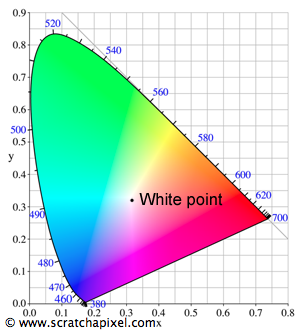

- **Gamut:** The complete subset of colors that can be accurately represented within a given color space or by a particular output device

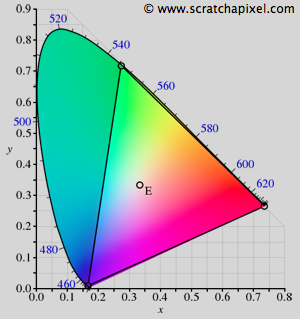

- **White point:** The specific color reference point considered "white" within a particular illuminant (light source) and color space. 

- **CIE standard observer color matching functions:** A set of curves representing the average human eye's sensitivity to different wavelengths of light. It helps us understand how humans perceive color.

- **Spectral intensity:** The amount of light power emitted or reflected at a specific wavelength. It implies the strength of a particular color component in the light.

- **The Macbeth Chart:** A standardized reference chart containing a variety of colored patches used to calibrate instruments and ensure consistent color reproduction across different devices. Imagine a color swatch book for the scientific world.

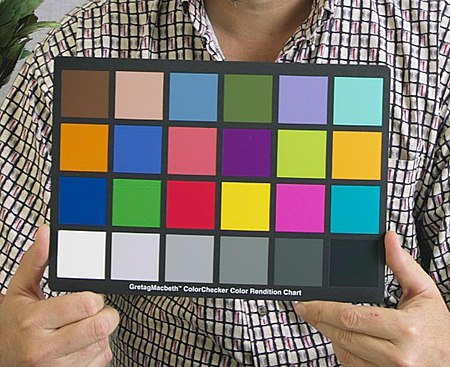

## III. The Macbeth Chart

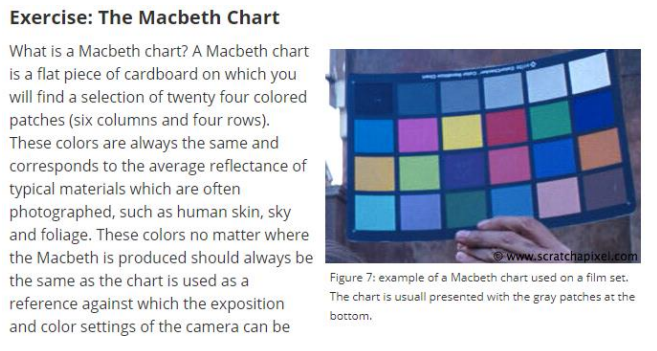

## IV. Tristimulus values

Tristimulus values are a set of three numbers (X, Y, and Z) that represent the amount of red, green, and blue light needed to create a specific color sensation in the human eye. Devices that rely on human color perception heavily utilize tristimulus values. Here are some key examples:

- **Colorimeters** measure the color of objects by capturing their spectral reflectance and converting it into tristimulus values (usually CIE XYZ). This allows for objective color comparison and communication, independent of human subjectivity in describing colors.

-  While d**isplays** use RGB or other additive color models to generate colors, they are ultimately calibrated to achieve specific tristimulus values that correspond to desired human color perception. This ensures a consistent color experience across different displays.

- **Digital Cameras** capture light information from a scene.  This information is then processed and converted into tristimulus values to represent the colors within the image in a way that aligns with human vision.

- Similar to displays, **printers** use a subtractive color model (CMYK) but are calibrated to achieve specific tristimulus values on paper. This ensures the printed colors match the intended colors as perceived by the human eye.

- Image editing and design **software for Color Correction and Design** often utilize tristimulus values to manipulate and analyze colors within an image. This allows for precise color adjustments and ensures colors are within the gamut of a specific output device.

## V. Color Matching Functions

The first column of the matrix `xyz31_1nm` includes wavelength information of the $\overline{x} \left(\lambda \right)$, $\bar{y} \left(\lambda \right)$, and $\bar{z} \left(\lambda \right)$ color-matching functions situated in the second, third and fourth column respectively. First we limit color-matching functions into the wavelength range 380-780nm.

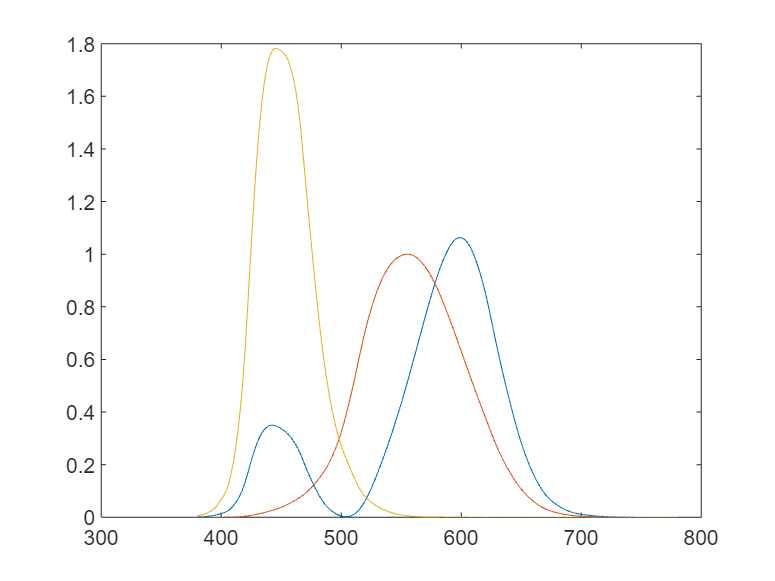

clear; clc; close all
load xyz31_1nm.mat
c = xyz31_1nm(21:2:421, 2:4);
plot(380:2:780, c)

## VI. Calculation of CIE 1931 XYZ-tristimulus values

The CIE 1931 XYZ-tristimulus values are calculated with equations:


$$X = k \sum_{\lambda=\lambda_a}^{\lambda_b} S(\lambda)\bar{x}(\lambda)\Delta\lambda
$$



$$Y = k \sum_{\lambda=\lambda_a}^{\lambda_b} S(\lambda)\bar{y}(\lambda)\Delta\lambda
$$



$$Y = k \sum_{\lambda=\lambda_a}^{\lambda_b} S(\lambda)\bar{y}(\lambda)\Delta\lambda
$$


where $S\left(\lambda \right)$ is physical color stimuli and $k$ is a normalizing constant. If stimuli $S\left(\lambda \right)$ is measured in units of spectral radiance, tristimulus value $Y$ becomes equal to photometric quantity luminance, when normalization constant $k$ is replaced with the maximum photopic luminous efficacy $K_m =683\;\mathrm{lm}\cdot W^{-1}$.

Develop different MATLAB code that can be used for calculating XYZ-tristimulus values. 

load D65_light.mat
spectralData = D65_light;
cmfData = xyz31_1nm;
XYZWavelengths = calculateXYZ(spectralData, cmfData);
head(XYZWavelengths, 4)

  360.0000    0.0008    0.0000    0.0037
  361.0000    0.0009    0.0000    0.0043
  362.0000    0.0011    0.0000    0.0049
  363.0000    0.0012    0.0000    0.0057



A MATLAB function program (m-file "calculateXYZ.m") that calculates XYZ for a given set of spectral data.

function XYZWavelengths = calculateXYZ(spectralData, cmfData)
    % spectralData is a 531x2 matrix: wavelength, Luminance
    % cmfData is a 471x4 matrix: wavelength, x, y, z (CMFs)

    % Extract wavelengths and check the common range
    spectralWavelengths = spectralData(:, 1);
    cmfWavelengths = cmfData(:, 1);
    
    % Find common wavelength range
    commonWavelengths = intersect(spectralWavelengths, cmfWavelengths);
    
    % Index the data to the common wavelength range
    [~, spectralIdx] = ismember(commonWavelengths, spectralWavelengths);
    [~, cmfIdx] = ismember(commonWavelengths, cmfWavelengths);
    
    % Extract the corresponding spectral intensity and CMF values
    spd = spectralData(spectralIdx, 2);
    xBar = cmfData(cmfIdx, 2);
    yBar = cmfData(cmfIdx, 3);
    zBar = cmfData(cmfIdx, 4);
    
    % Calculate XYZ by integrating over the common wavelength range
    deltaX = 1;  % Wavelength interval is 1 nm
    X = spd .* xBar * deltaX;
    Y = spd .* yBar * deltaX;
    Z = spd .* zBar * deltaX;
    
    % Assemble the output matrix with wavelengths and corresponding XYZ
    XYZWavelengths = [commonWavelengths, X, Y, Z];
end

*Reference: *[Introduction to Light, Color and Color Space (scratchapixel.com)](https://www.scratchapixel.com/lessons/digital-imaging/colors/color-space.html)